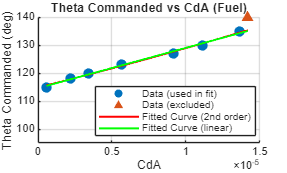



% FUEL EREG
fuelClose = 95;
fuelOpen = 140;
fuelCracking = 108;

thetaCommandedArray     = [115 118 120 123 127 130 135 140];
upstreamPressureArray   = [6.78 6.17 5.55 4.53 3.59 3.76 3.19 3.57] * 1e5;
downstreamPressureArray = [1.03 1.21 1.40 1.74 2.04 2.38 2.31 2.59] * 1e5;
mdotArray               = [0.0195 0.0691 0.0981 0.1336 0.1611 0.1845 0.1810 0.1984];

nFitPoints = numel(thetaCommandedArray) - 1;  % exclude final point from fitting only

relationStructFuel = struct('thetaCommanded', {}, 'thetaPercentage', {}, 'dP', {}, 'CdA', {}, 'Kv', {});

for i = 1:numel(thetaCommandedArray)
    thetaCommanded      = thetaCommandedArray(i);
    upstreamPressure    = upstreamPressureArray(i);
    downstreamPressure  = downstreamPressureArray(i);
    mdot                = mdotArray(i);

    CdA = getCdAfromData(upstreamPressure, downstreamPressure, mdot, 1000);
    Kv  = CdA * 50900;
    thetaPercentage = (thetaCommanded - fuelClose) * 100 / (fuelOpen - fuelClose);
    dP = upstreamPressure - downstreamPressure;
    dP = dP * 1e-05;
    relationStructFuel(i) = struct('thetaCommanded', thetaCommanded, ...
                                'thetaPercentage', thetaPercentage, ...
                                'dP', dP,...
                                'CdA', CdA, ...
                                'Kv', Kv);
end

save('CdARelationship.mat', 'relationStructFuel');

allThetaPercentages = [relationStructFuel.thetaPercentage];
allAngles = [relationStructFuel.thetaCommanded];
allCdA = [relationStructFuel.CdA];
allKvs = [relationStructFuel.Kv];

% Fit only on the first nFitPoints, excluding the last point
quadraticFitFuel = polyfit(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 2);
linearFitFuel = polyfit(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 1);
linearFitFuelTrans = polyfit(allAngles(1:nFitPoints), allCdA(1:nFitPoints), 1);
linearFitFuelKv = polyfit(allKvs(1:nFitPoints), allAngles(1:nFitPoints), 1);

% Plot collected data points (CdA on x, theta on y)
figure;
scatter(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 60, 'filled', 'MarkerFaceColor', [0 0.4470 0.7410]);
hold on;
scatter(allCdA(end), allAngles(end), 60, 'filled', 'Marker', '^', 'MarkerFaceColor', [0.8500 0.3250 0.0980]);

% Evaluate both fitted curves over the CdA data range (all points, including excluded one)
CdAFit = linspace(min(allCdA), max(allCdA), 500);
thetaFitQuad = polyval(quadraticFitFuel, CdAFit);
thetaFitLinear = polyval(linearFitFuel, CdAFit);

plot(CdAFit, thetaFitQuad, 'r-', 'LineWidth', 1.5);
plot(CdAFit, thetaFitLinear, 'g-', 'LineWidth', 1.5);

xlabel('CdA');
ylabel('Theta Commanded (deg)');
title('Theta Commanded vs CdA (Fuel)');
legend('Data (used in fit)', 'Data (excluded)', 'Fitted Curve (2nd order)', 'Fitted Curve (linear)', 'Location', 'best');
grid on;
ylim([fuelClose fuelOpen]);
hold off;

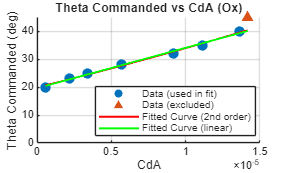


% EXPECTED OX EREG RELATIONSHIP
oxClose = 0;
oxOpen = 45;
oxCracking = 13;

commandDiff = oxClose - fuelClose;
thetaCommandedArray = thetaCommandedArray + commandDiff;

relationStructOx = struct('thetaCommanded', {}, 'thetaPercentage', {}, 'dP', {}, 'CdA', {}, 'Kv', {});

for i = 1:numel(thetaCommandedArray)
    thetaCommanded      = thetaCommandedArray(i);
    upstreamPressure    = upstreamPressureArray(i);
    downstreamPressure  = downstreamPressureArray(i);
    mdot                = mdotArray(i);

    CdA = getCdAfromData(upstreamPressure, downstreamPressure, mdot, 1000);
    Kv  = CdA * 50900;
    thetaPercentage = (thetaCommanded - oxClose) * 100 / (oxOpen - oxClose);
    dP = upstreamPressure - downstreamPressure;
    dP = dP * 1e-05;
    relationStructOx(i) = struct('thetaCommanded', thetaCommanded, ...
                                'thetaPercentage', thetaPercentage, ...
                                'dP', dP,...
                                'CdA', CdA, ...
                                'Kv', Kv);
end

save('CdARelationship.mat', 'relationStructOx', '-append');

allThetaPercentages = [relationStructOx.thetaPercentage];
allAngles = [relationStructOx.thetaCommanded];
allCdA = [relationStructOx.CdA];
allKvs = [relationStructOx.Kv];

quadraticFitOx = polyfit(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 2);
linearFitOx = polyfit(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 1);
linearFitOxKv = polyfit(allKvs(1:nFitPoints), allAngles(1:nFitPoints), 1);
figure;
scatter(allCdA(1:nFitPoints), allAngles(1:nFitPoints), 60, 'filled', 'MarkerFaceColor', [0 0.4470 0.7410]);
hold on;
scatter(allCdA(end), allAngles(end), 60, 'filled', 'Marker', '^', 'MarkerFaceColor', [0.8500 0.3250 0.0980]);

CdAFit = linspace(min(allCdA), max(allCdA), 500);
thetaFitQuad = polyval(quadraticFitOx, CdAFit);
thetaFitLinear = polyval(linearFitOx, CdAFit);

plot(CdAFit, thetaFitQuad, 'r-', 'LineWidth', 1.5);
plot(CdAFit, thetaFitLinear, 'g-', 'LineWidth', 1.5);

xlabel('CdA');
ylabel('Theta Commanded (deg)');
title('Theta Commanded vs CdA (Ox)');
legend('Data (used in fit)', 'Data (excluded)', 'Fitted Curve (2nd order)', 'Fitted Curve (linear)', 'Location', 'best');
grid on;
ylim([oxClose oxOpen]);
hold off;


valveAngleArray = linspace(fuelClose, fuelOpen, 100)

valveAngleArray =    95.0000   95.4545   95.9091   96.3636   96.8182   97.2727   97.7273   98.1818   98.6364   99.0909   99.5455  100.0000  100.4545  100.9091  101.3636  101.8182  102.2727  102.7273  103.1818  103.6364  104.0909  104.5455  105.0000  105.4545  105.9091  106.3636  106.8182  107.2727  107.7273  108.1818  108.6364  109.0909  109.5455  110.0000  110.4545  110.9091  111.3636  111.8182  112.2727  112.7273  113.1818  113.6364  114.0909  114.5455  115.0000  115.4545  115.9091  116.3636  116.8182  117.2727


valveFractionVector = (valveAngleArray - fuelClose)/(fuelOpen - fuelClose)

valveFractionVector =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


orificeAreaVector = zeros(size(valveFractionVector))

orificeAreaVector =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:numel(valveAngleArray)
    Angle = valveAngleArray(i);
    if Angle <= fuelCracking
        orificeAreaVector(i) = 1e-10 + 1e-11*i ;
    else
        orificeAreaVector(i) = max(1e-10 + 1e-11*i,polyval(linearFitFuelTrans, Angle));
    end
end